## `Zadanie 1`

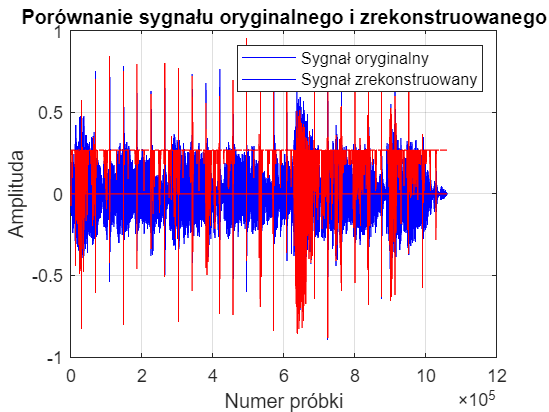

clear all; close all;

[x, fs] = audioread('DontWorryBeHappy.wav');
x = double(x);

a = 0.9545;

% sprawdzenie, czy x jest wektorem kolumnowym, jeśli tak, przekształcamy na wektor wierszowy
if iscolumn(x)
    x = x';
end

% KODER
d = zeros(size(x));  
d(1) = x(1);
for n = 2:length(x)
    d(n) = x(n) - a * x(n-1);
end

dq = lab11_kwant(d);    

% DEKODER
y = zeros(size(x));
y(1) = dq(1);           % inicjalizacja pierwszej próbki dekodera
for n = 2:length(dq)    % zmiana z length(x) na length(dq)
    y(n) = dq(n) + a * y(n-1);
end

% porównanie sygnału oryginalnego z sygnałem zrekonstruowanym
figure(1);
n = 1:length(x); 
plot(n, x, 'b', n, y, 'r'); grid on;
legend('Sygnał oryginalny', 'Sygnał zrekonstruowany');
title('Porównanie sygnału oryginalnego i zrekonstruowanego');
xlabel('Numer próbki'); ylabel('Amplituda');

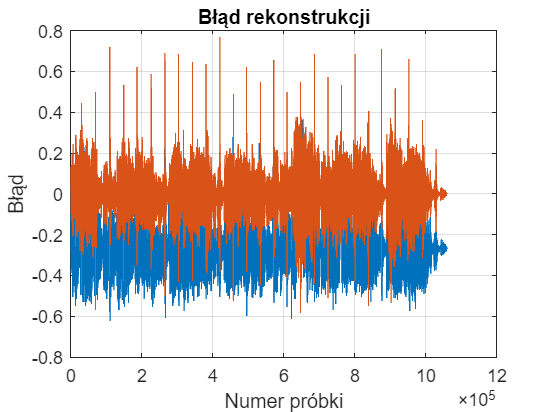


% wyznaczenie błędów rekonstrukcji
error = x - y;
figure(2); plot(n, error);
title('Błąd rekonstrukcji'); grid on;
xlabel('Numer próbki'); ylabel('Błąd');

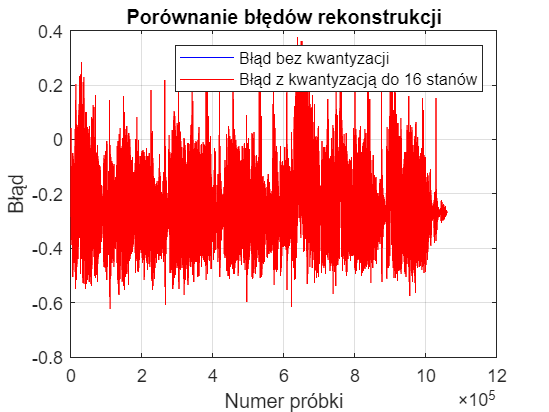


dq_16 = lab11_kwant(d); % kwantyzacja do 16 stanów

% DEKODER z kwantyzacją do 16 stanów
y_16 = zeros(size(x));
y_16(1) = dq_16(1);         % inicjalizacja pierwszej próbki dekodera
for n = 2:length(dq_16)     % zmiana z length(x) na length(dq_16)
    y_16(n) = dq_16(n) + a * y_16(n-1);
end

% porównanie błędów rekonstrukcji dla obu przypadków
error_16 = x - y_16;
min_length = min(length(error), length(error_16));
n = 1:min_length;

figure(3); plot(n, error(1:min_length), 'b', n, error_16(1:min_length), 'r');
legend('Błąd bez kwantyzacji', 'Błąd z kwantyzacją do 16 stanów'); grid on;
title('Porównanie błędów rekonstrukcji'); xlabel('Numer próbki'); ylabel('Błąd');


% wyniki
disp('Błąd średniokwadratowy bez kwantyzacji:');

Błąd średniokwadratowy bez kwantyzacji:


disp(mean(error.^2));

    0.0703    0.0059



disp('Błąd średniokwadratowy z kwantyzacją do 16 stanów:');

Błąd średniokwadratowy z kwantyzacją do 16 stanów:


disp(mean(error_16.^2));

    0.0703    0.0059



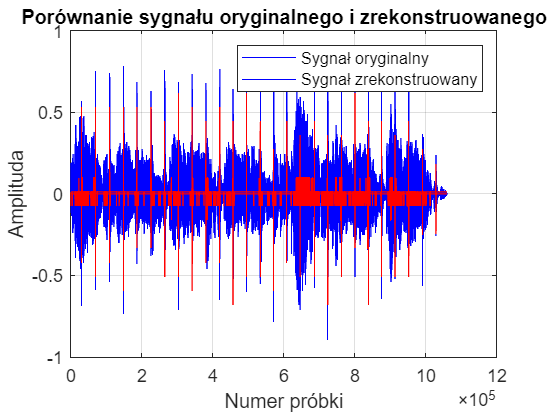


% porównanie sygnału oryginalnego z sygnałem zrekonstruowanym
% figure(10);
% n = 1:length(x); 
% plot(n, x, 'b', n, dq, 'r'); grid on;
% legend('Sygnał oryginalny', 'Sygnał zrekonstruowany');
% title('Porównanie sygnału oryginalnego i zrekonstruowanego');
% xlabel('Numer próbki'); ylabel('Amplituda');

function dq = lab11_kwant(d)
    % funkcja kwantyzująca sygnał d do 16 stanów (4 bity)
    d_min = min(d);
    d_max = max(d);
    num_levels = 16;        % liczba stanów
    step_size = (d_max - d_min) / (num_levels - 1);
    
    % kwantyzacja
    dq = round((d - d_min) / step_size) * step_size + d_min;
end
